# **Beyond Introduction to Programming**

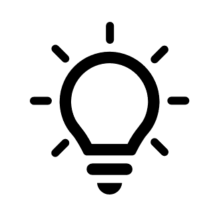 Where do I find MATLAB? [Here](https://www.mathworks.com/academia/tah-portal/wits-university-40783970.html)!

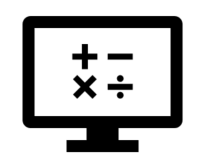 Do I have to have MATLAB installed on my computer right now? No, you can use  [MALAB Online](https://matlab.mathworks.com/)!

## Recap of Week 6, Part 2: Interoperability

This week in part 2, we learnt about: 

- Interoperability with other languages

- MATLAB and Python 

In the next part of this week's content, we will be demonstrating Beyond Introduction to Programming, covering the following sub-topics: 

- Symbolic Math

- Object-Oriented Programming (OOP)

- Simulink

## Beyond the Introduction to Programming

In this course, we only scrapped the surface of the programming you will likely encounter in the future. It was built with the intention to supply you with a good starting point, and to show you that you too can be programmer. This last section is dedicated to introducing you three other approaches to programming that you may encounter some time in your future.

### Symbolic Math

The [Symbolic Math Toolbox™](https://www.mathworks.com/products/symbolic.html) has been designed to assist a user with algebraic computation (algorithms and software for manipulating mathematical expressions and other mathematical objects). For example, you can learn concepts from calculus and applied mathematics using this type of computation. Let us consider an example that shows introductory functions like `fplot` and `diff`. 

To manipulate a symbolic variable, create an object of type `syms`.

syms x

Once a symbolic variable is defined, you can build and visualize functions with `fplot`. 

f(x) = 1/(5+4*cos(x))

$$f(x) = \frac{1}{4\,\cos\left(x\right)+5}$$

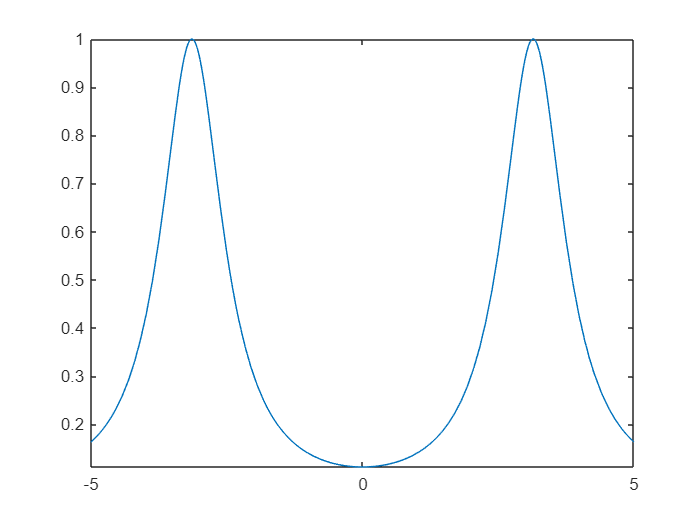

fplot(f)

Many functions can work with symbolic variables. For example, `diff` differentiates a function.

f1 = diff(f) 

$$f1(x) = \frac{4\,\sin\left(x\right)}{{\left(4\,\cos\left(x\right)+5\right)}^{2}}$$

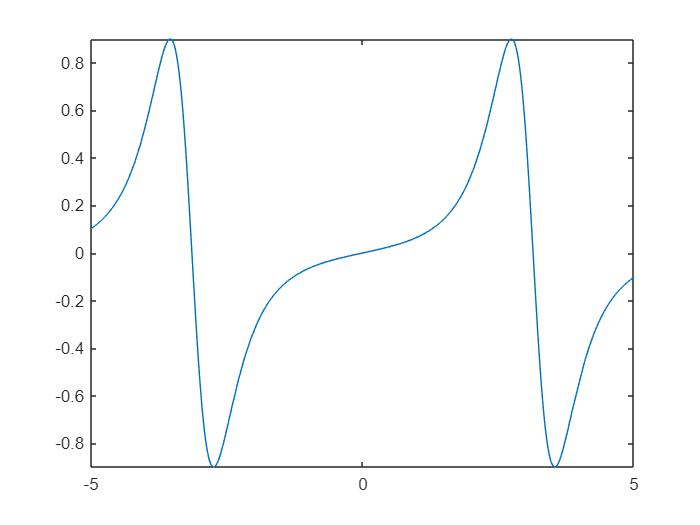

fplot(f1) 

The above is just one example of how algebraic computation can be leveraged, so I encourage you to visit the [Getting started with the Symbolic Math Toolbox](https://www.mathworks.com/help/symbolic/getting-started-with-symbolic-math-toolbox.html?s_tid=CRUX_topnav) for more ideas on how this approach can assist your workflow. 

Now you try! Use the `fplot` function to create a plot of `sin(x)`, `cos(x)`, and `tan(x)` on the same set of simultaneously. 

Hint: Combine the three trigonometric functions in an array, and remember to define `x` as a symbolic variable. 

Another way to leverage symbolic math in your workflow is to use the Symbolic Math Live Tasks. You can find these by selecting the *Insert* tab in your Toolstrip when working in a Live Script, and selecting the task you would like to perform. The following Live Tasks are currently available when you have the Symbolic Math Toolbox installed: 

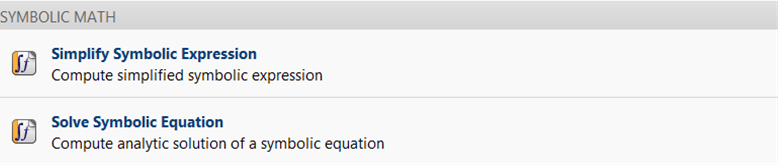

Let us try out the Solve Symbolic Equation task for the equation $3\;x^2 =27$, solving for the variable `x`. 

syms x
eqn = 3*x^2 == 27;

% Compute analytic solution of a symbolic equation
solution = solve(eqn,x);
% Display symbolic solution returned by solve
displaySymSolution(solution);

Note: You can always check what code was executed by clicking on the dropdown arrow in the middle of the task interface, above the provided solution. i.e. this task executed the following commands to achieve the output we were supplied. 

solution = solve(eqn,x);
% Display symbolic solution returned by solve
displaySymSolution(solution);

$$solution = \left(\begin{array}{c} -3\\ 3 \end{array}\right)$$

### Object-Oriented Programming (OOP)

Object-oriented programming is a design approach that enables you to programmatically define structures called *objects* that combine data (properties) together with functions that operate on that data (methods). In MATLAB, you can create objects that model the behaviour of devices and systems in the real world. Those objects can then be used as building blocks in applications used to simulate and analyse complex systems.

A Class in MATLAB follows a particular convention that needs to be followed when creating your own Class. A quick and convenient way for creating a new class is to autogenerate a Class template by navigating to the *Home tab* in the Toolstrip, selecting *New*, and then either a *Class*, *Test Class*, and *System Object* depending on your needs. This workflow is illustrated in the following graphic. 

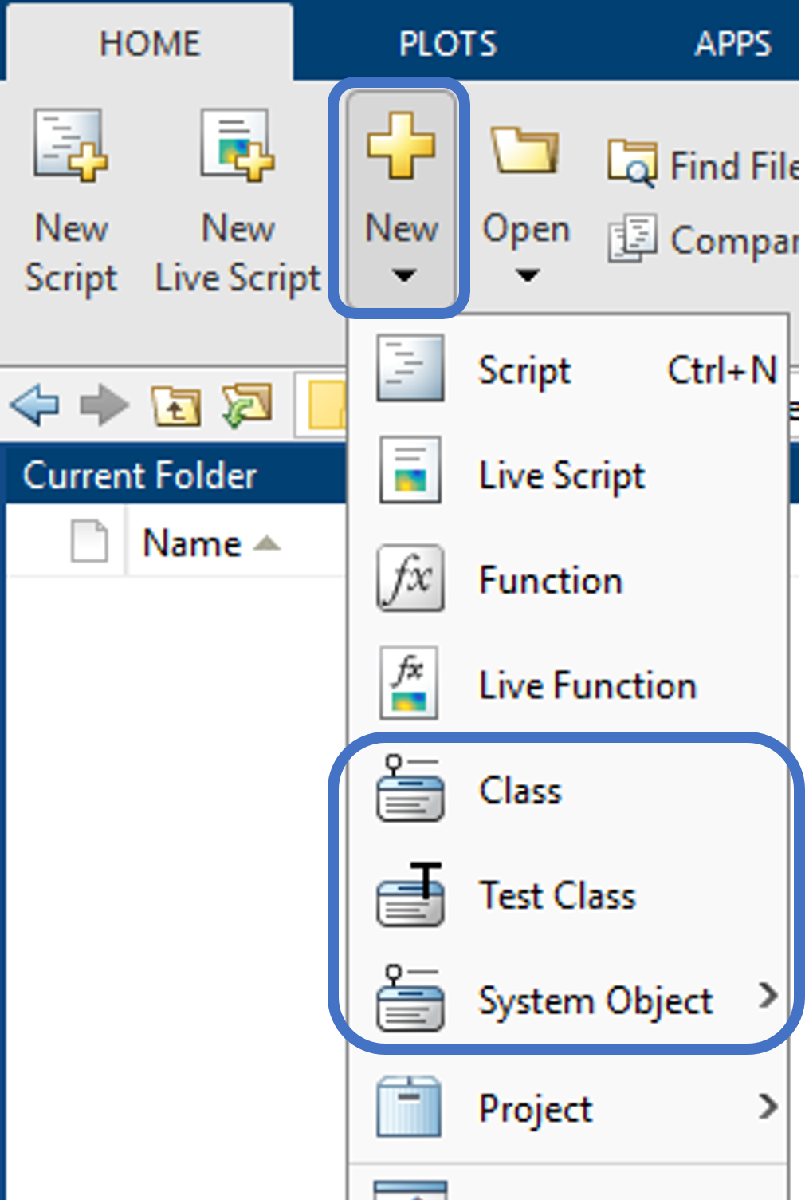

Let us follow the workflow when a *Class* template has been selected. The following template is supplied in a new script file: 

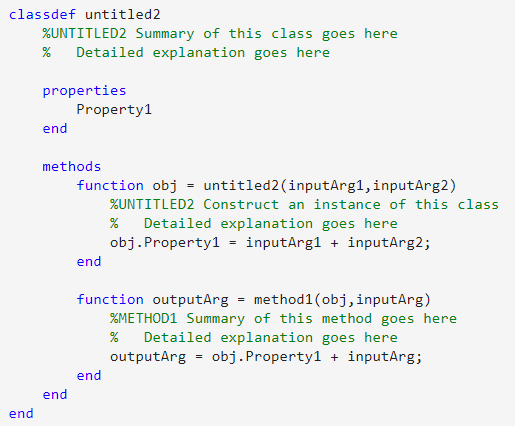

Notice that each section has been labelled and a description has been given in green (following a single %). A class can be broken up into two sections; `properties`, and `methods`. These can be thought of in the following manner: 

- **Properties** are **nouns** 

- **Methods** are **verbs** 

Object-Oriented Programming offers the following four major benefits over procedural and functional programming methods: 

- **Abstraction** - Simplify your program by using classes that generalise the object types

- **Encapsulation** - Being able to define a scope for a particular object prevents the user of the object from becoming dependent on an implementation details or characteristic (risk of changing or breaking the code)  

- **Inheritance** - Classes can inherit from one another, allowing you to reuse more of your code

- **Polymorphism** - A single class can be used to create multiple objects with ease and flexibility

For a basic example of OOP in MATLAB, please consult this [Technical Article: Introduction to Object-Oriented Programming in MATLAB](https://www.mathworks.com/company/newsletters/articles/introduction-to-object-oriented-programming-in-matlab.html), where tuart McGarrity and Adam Sifounakis cover the OOP workflow development for analysing sensor array data. 

### Simulink

Simulink is a block diagram environment used to design systems with multidomain models, simulate before moving to hardware, and deploy without writing code. It allows for us to visualise an intuitive approach for modelling equations and systems. It forms a foundation for Model-Based Design, including multidomain system modelling, real-time testing, automatic code generation, and verification and validation. 

To demonstrate how simple this block diagram environment can be leveraged in your workflow, let us consider the implementation of an equation model that converts a temperature in degrees Celsius to degrees Fahrenheit. The equation for this conversion is

$^{\circ } F\;=\;32\;+^{\circ } C$(9/5)

and the Simulink implementation of this has been screenshot in the following image. 

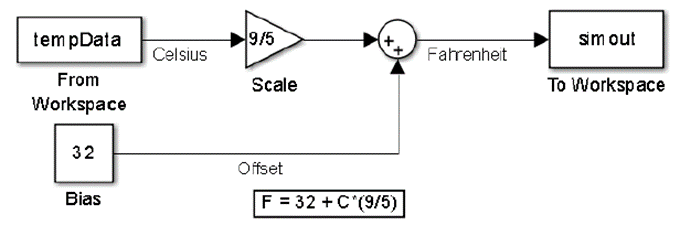

Watch [this short video](https://www.mathworks.com/videos/simulink-overview-61216.html) for the Simulink overview, and if you want to know more about deployment to hardware, then take a look at the following links: 

- [Getting Started with Arduino Hardware](https://www.mathworks.com/help/supportpkg/arduino/ref/getting-started-with-arduino-hardware.html)

- [Run Model on Arduino Hardware](https://www.mathworks.com/help/supportpkg/arduino/ug/run-model-on-arduino-hardware.html)

- [MathWorks Minidrone Competitions Page](https://www.mathworks.com/academia/student-competitions/minidrones.html)

- [Vehicle Modeling Using Simulink](https://www.mathworks.com/videos/matlab-and-simulink-racing-lounge-vehicle-modeling-part-1-simulink-1502466996305.html)

- [Deploying a Deep Learning-Based State-of-Charge (SoC) Estimation Algorithm to NXP S32K3 Microcontrollers](https://www.mathworks.com/videos/deploying-a-deep-learning-based-state-of-charge-soc-estimation-algorithm-to-nxp-s32k3-microcontrollers-1638200087678.html)

As an example, let us consider a bouncing ball example. You can access this by running the following code cell: 

openExample('simulink_general/sldemo_bounceExample')

$$solution = \left(\begin{array}{c} -3\\ 3 \end{array}\right)$$

A Simulink model will open with the following configuration: 

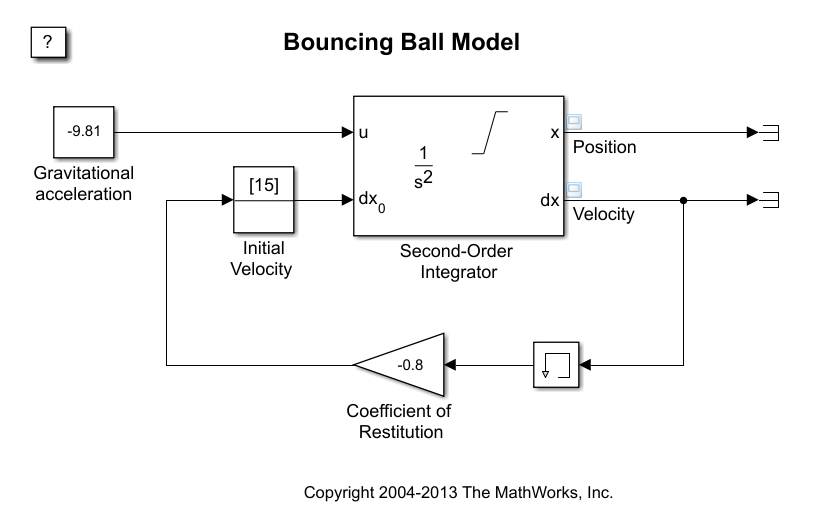

The model itself was built on the equations of motion given some initial conditions. This type of example could have been done in MATLAB too, but this approach was to show you how easy and intuitive the design of a solution can be executed in the Simulink environment. Click on the Run button, and viewer window will pop up showing the position and velocity of the ball at different points in time in the simulation. 

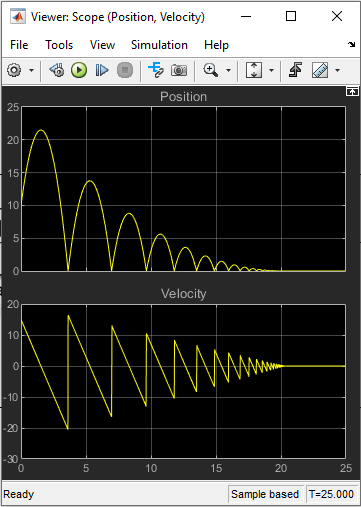

## What we've covered this week in part 3: Beyond Introduction to Programming

This week in part 3, we learnt about: 

- Symbolic Math

- Object-Oriented Programming (OOP)

- Simulink

## **PowerPoint Presentation**

- Week_6_Part_3_Beyond_Introduction_to_Programming_Solution.pptx

## Extra resources

- [Documentation example: Create Symbolic Matrix Variables](https://www.mathworks.com/help/symbolic/use-symbolic-matrix-variables.html)

- [Video tutorial: Developing Classes Overview](https://www.mathworks.com/videos/developing-classes-overview-68982.html)

- [Documentation: OOP Property Attributes](https://www.mathworks.com/help/matlab/matlab_oop/property-attributes.html)

- [Documentation: OOP Method Attributes](https://www.mathworks.com/help/matlab/matlab_oop/method-attributes.html)

- [Documentation: OOP Validate Property Values](https://www.mathworks.com/help/matlab/matlab_oop/validate-property-values.html)

- [Documentation: Create a simple model using Simulink](https://www.mathworks.com/help/simulink/gs/create-a-simple-model.html) 

- [Video: IoT from Data to Action, Part 1: Getting started with ThingSpeak](https://www.mathworks.com/videos/iot-from-data-to-action-part-1-getting-started-with-thingspeak-1633414543881.html)

- [Simulink Onramp self-paced course](https://www.mathworks.com/learn/tutorials/simulink-onramp.html)

- [Simulink Fundamentals self-paced course](https://matlabacademy.mathworks.com/details/simulink-fundamentals/slbe) 

- [Machine Learning with MATLAB](https://matlabacademy.mathworks.com/details/machine-learning-with-matlab/mlml) 

- [Deep Learning with MATLAB](https://matlabacademy.mathworks.com/details/deep-learning-with-matlab/mldl)

- [Self-Paced Online Courses](https://matlabacademy.mathworks.com/)

## References

- [Getting started with Symbolic Math Toolbox](https://www.mathworks.com/help/symbolic/getting-started-with-symbolic-math-toolbox.html)

- [Learn Calculus in the Live Editor](https://www.mathworks.com/help/symbolic/learn-calculus.html) 

- [Object-Oriented Programming in MATLAB](https://www.mathworks.com/products/matlab/object-oriented-programming.html) 

- [Technical Article: Introduction to Object-Oriented Programming in MATLAB](https://www.mathworks.com/company/newsletters/articles/introduction-to-object-oriented-programming-in-matlab.html) 

- [Product page: Simulink](https://www.mathworks.com/products/simulink.html)

- [Virtual lab: Air-track collisions](https://www.mathworks.com/academia/courseware/air-track-collisions.html) 

- [Documentation: Simulation of a bouncing ball](https://www.mathworks.com/help/simulink/slref/simulation-of-a-bouncing-ball.html)

***Copyright 2022 The MathWorks, Inc. & Opti-Num Solutions (Pty) Ltd. ***